# Set Options When Importing Categorical Data

Use the `setvaropts` function to update properties that control the import of `categorical` data. First, get the import options object for the file. Next, examine and update the options for the categorical variables. Finally, import the variables using the `readtable` function.

Preview the data in `outages.csv`. Notice the categorical data in the columns `Region` and `Cause`. This table shows only the first 10 rows.

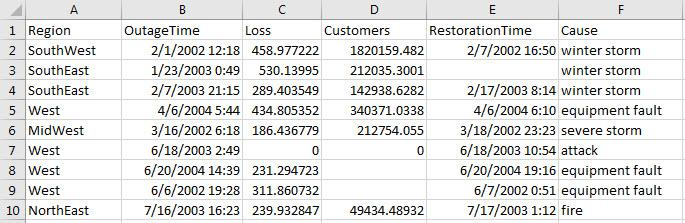

Get the import options object.

opts = detectImportOptions('outages.csv');

Get and examine the options for the variables `Region` and `Cause`.

getvaropts(opts,{'Region','Cause'})

Set the data type of the variables to `categorical`.

opts = setvartype(opts,{'Region','Cause'},'categorical');

Set the `FillValue` property of the variables to replace missing values with category name `'Miscellaneous'`. Set `TreatAsMissing` property to `'unknown'`.

opts = setvaropts(opts,{'Region','Cause'},...
                                   'FillValue','Miscellaneous',...
                                   'TreatAsMissing','unknown');

Select, read, and display a summary of the two variables.

opts.SelectedVariableNames = {'Region','Cause'};
T = readtable('outages.csv',opts); 
summary(T)

*Copyright 2012 The MathWorks, Inc.*